# Uso de imagenes para apoyo en clasificación

Se propone el siguiente flujo de operación:

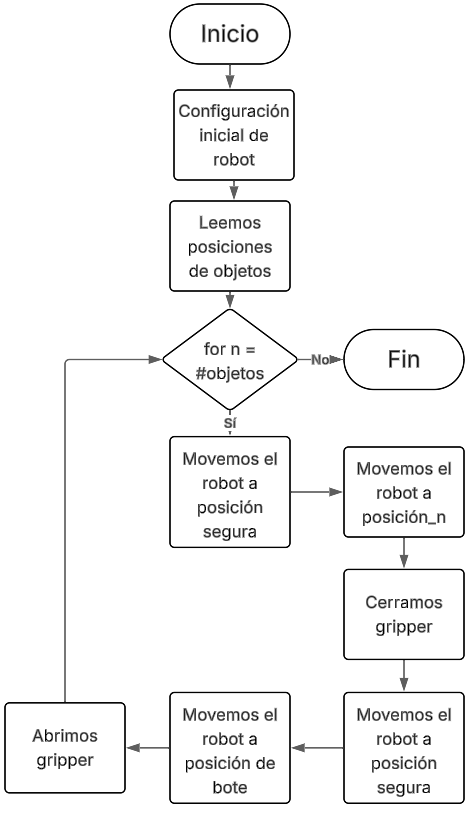>>>------------------------>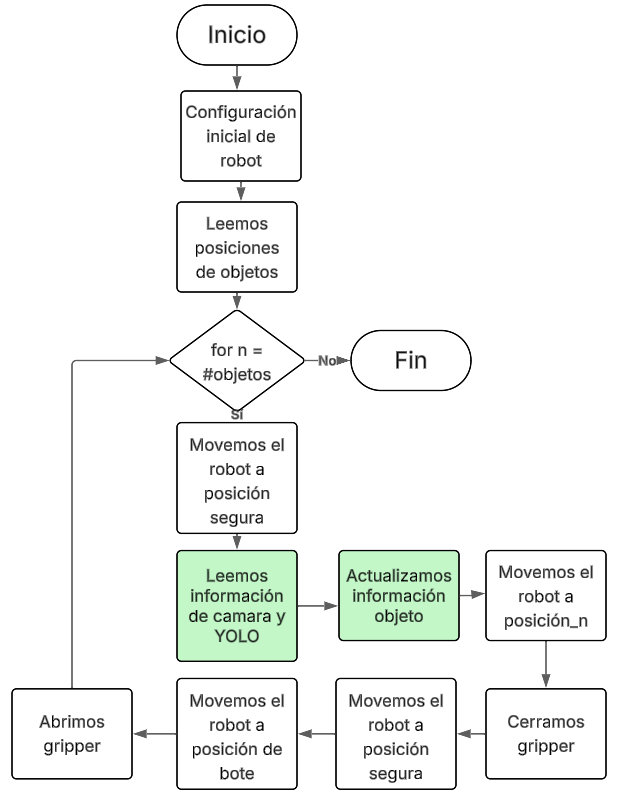

clear all
% Configuración inicial del robot
rosIP = '172.17.0.1';
[jointSub,trajGoal,trajAct,gripGoal,gripAct,rgbImgSub,rgbDptSub] = IniciarRobot(rosIP);

Initializing global node /matlab_global_node_08008 with NodeURI http://PCIrandi:40789/ and MasterURI http://172.17.0.1:11311.
/camera/depth/camera_info                                  
/camera/depth/image_raw                                    
/camera/depth/points                                       
/camera/parameter_descriptions                             
/camera/parameter_updates                                  
/camera/rgb/camera_info                                    
/camera/rgb/image_raw                                      
/clock                                                     
/ft_sensor/raw                                             
/gazebo/link_states                                        
/gazebo/model_states                                       
/gazebo/parameter_descriptions                             
/gazebo/parameter_updates                                  
/gazebo/performance_metrics                                
/gazebo/set_link_state            


q = zeros(6,1);

Buscamos objetos desconocidos con posición y orientación indefinidos. Las latas y botella, se encuentran por ejemplo en:

Lata_1: $\left(x,y,z\right)=\left(0\ldotp 325,0,-0\ldotp 08\right)$

Botella_1: $\left(x,y,z\right)=\left(0\ldotp 343,-0\ldotp 227,-0\ldotp 08\right)$

Botella_2: $\left(x,y,z\right)=\left(0\ldotp 325,0\ldotp 151,0\ldotp 06\right)$

%% Buscamos la posición de algunos objetos y botes de disposición final de forma manual
gripperX = 0.343;
gripperY = -0.227;
gripperZ = 0.3;


gripperTheta = -1.57;


q = MoverRobotXYZ(gripperX,gripperY,gripperZ,gripperTheta,q,trajAct,trajGoal,jointSub);

Error using ros.Subscriber/receive (line 465)
The function did not receive any data and timed out.

Error in LeerValoresArticulares (line 2)
    jointStateMsg = receive(jointSub,3);

Error in MoverRobot (

rgbImg = rosReadImage(rgbImgSub.LatestMessage);
imshow(rgbImg)

Prompt en ChatGPT: *Coloca una linea vertical y horizontal a la mitad de una foto en matlab*

hold on;

% Obtener dimensiones
[alto, ancho, ~] = size(rgbImg);

% Coordenadas del centro
x_centro = ancho / 2;
y_centro = alto / 2;

% Dibujar línea vertical en el centro
line([x_centro x_centro], [1 alto], 'Color', 'r', 'LineWidth', 2);

% Dibujar línea horizontal en el centro
line([1 ancho], [y_centro y_centro], 'Color', 'r', 'LineWidth', 2);


% hold off;
% impixelinfo

Prompt en ChatGPT: Dibuja un punto en el punto (320,300)

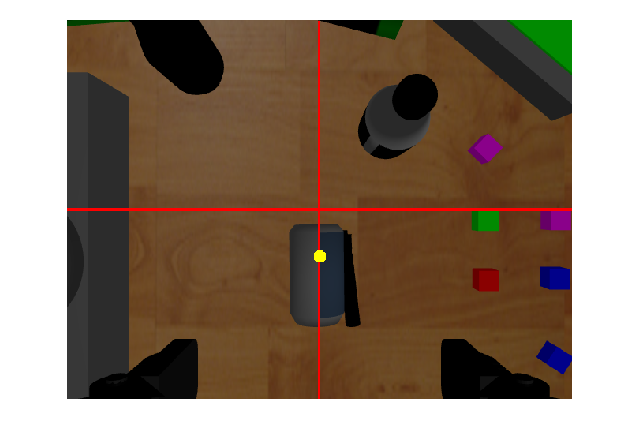

% Coordenadas del punto
x = 320;
y = 300;

% Dibujar punto rojo en (320, 300)
plot(x, y, 'yo', 'MarkerSize', 8, 'LineWidth', 2 , 'MarkerFaceColor','y');  % 'ro' = rojo con círculo

hold off;

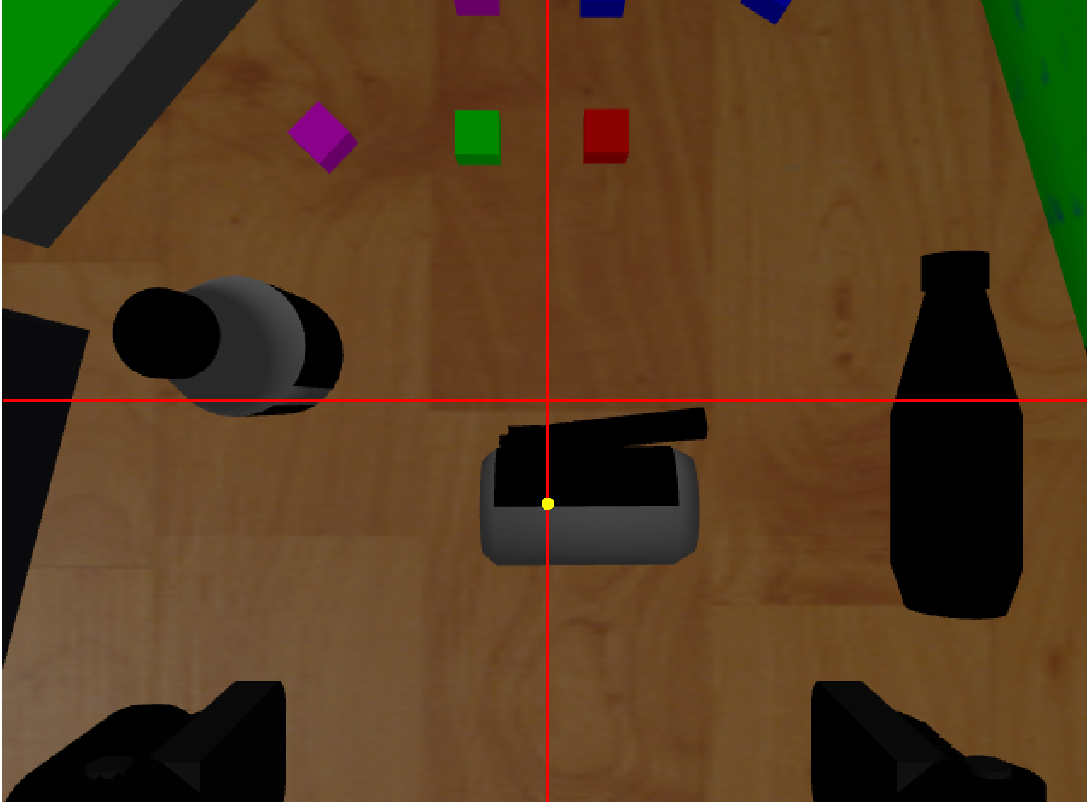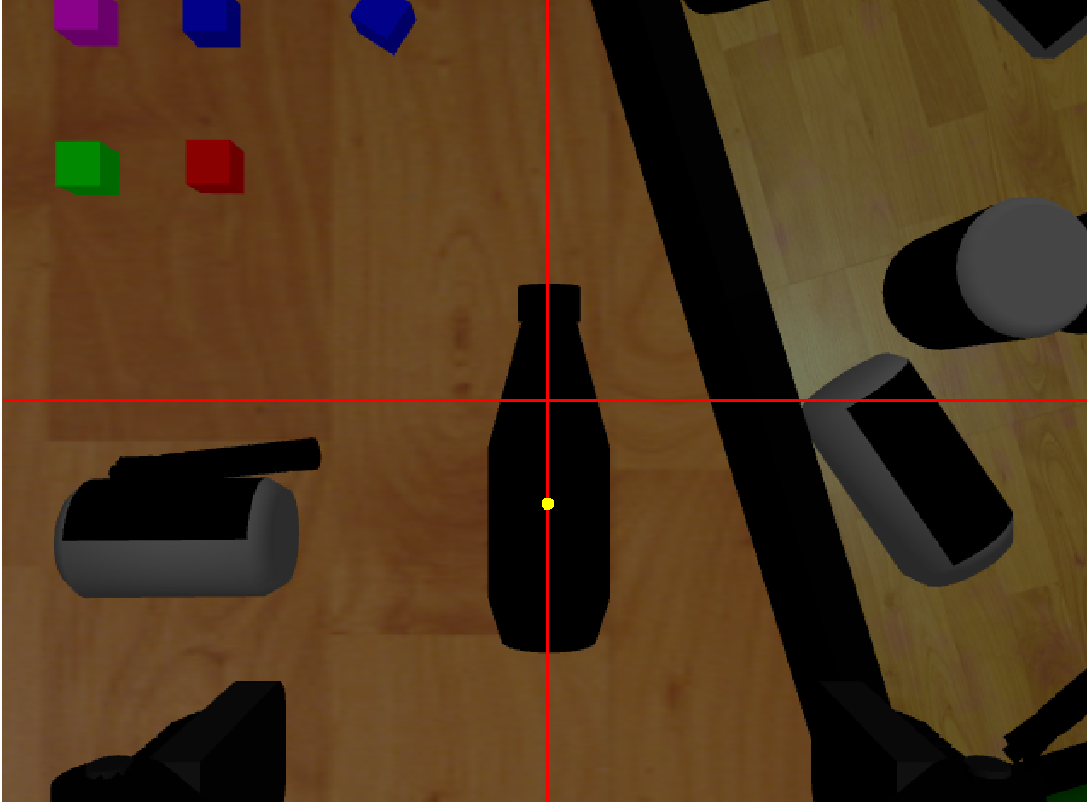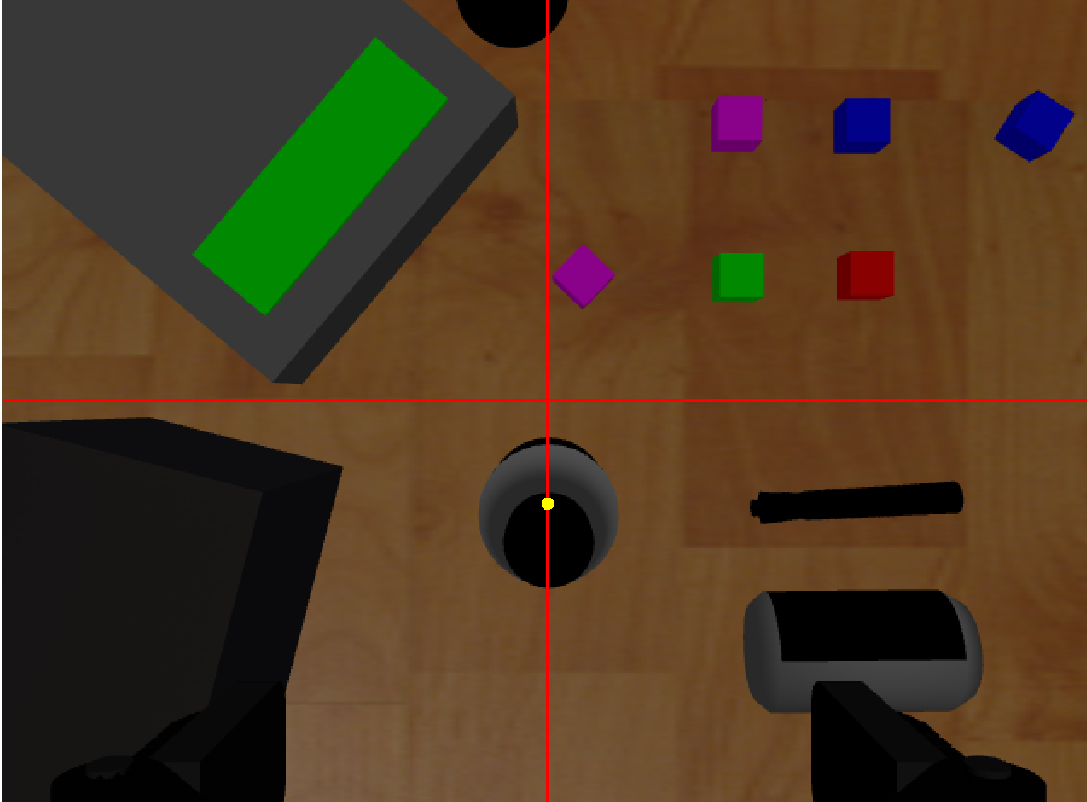

clear all
% Configuración inicial del robot
rosIP = '172.17.0.1';
[jointSub,trajGoal,trajAct,gripGoal,gripAct,rgbImgSub,rgbDptSub] = IniciarRobot(rosIP);

q = zeros(6,1);

% Se leen las posiciones de los objetos, quedando 
objeto(1) = struct('objeto', NaN , 'x', 0.325 , 'y',  0.000 , 'z' , -0.08 , 'orientacion',  0.00 , 'Bote', NaN , 'gripper' , NaN);
objeto(2) = struct('objeto', NaN , 'x', 0.343 , 'y', -0.227 , 'z' , -0.08 , 'orientacion', -1.57 , 'Bote', NaN , 'gripper' , NaN);
objeto(3) = struct('objeto', NaN , 'x', 0.325 , 'y',  0.151 , 'z' ,  0.06 , 'orientacion',  0.00 , 'Bote', NaN , 'gripper' , NaN);

bote(1) = struct('color', 0 , 'x', -0.38, 'y', 0.4 , 'z' ,  0.2 , 'orientacion', 0  );
bote(2) = struct('color', 1 , 'x', -0.38, 'y', -0.4 , 'z' ,  0.2 , 'orientacion', 3.14  );

  1×3 struct array with fields:

    objeto
    x
    y
    z
    orientacion
    Bote
    gripper



%Movimiento a zona segura de recolección de forma manual
n = 1;
gripperX = objeto(n).x;
gripperY = objeto(n).y;
gripperZ = objeto(n).z;
gripperTheta = objeto(n).orientacion;
q = MoverRobotXYZ(gripperX,gripperY,gripperZ,gripperTheta,q,trajAct,trajGoal,jointSub);

Initializing global node /matlab_global_node_62942 with NodeURI http://PCIrandi:35737/ and MasterURI http://172.17.0.1:11311.
/camera/depth/camera_info                                  
/camera/depth/image_raw                                    
/camera/depth/points                                       
/camera/parameter_descriptions                             
/camera/parameter_updates                                  
/camera/rgb/camera_info                                    
/camera/rgb/image_raw                                      
/clock                                                     
/ft_sensor/raw                                             
/gazebo/link_states                                        
/gazebo/model_states                                       
/gazebo/parameter_descriptions                             
/gazebo/parameter_updates                                  
/gazebo/performance_metrics                                
/gazebo/set_link_state            

    2.3003
   -0.7556
   -1.9701
   -1.9868
    1.5708
    0.7295

    1.5149
   -0.7556
   -1.9701
   -1.9868
    1.5708
    0.7295

    0.7295
   -0.7556
   -1.9701
   -1.9868
    1.5708
    0.7295

   -0.0559
   -0.7556
   -1.9701
   -1.9868
    1.5708
    0.7295

   -0.8413
   -0.7556
   -1.9701
   -1.9868
    1.5708
    0.7295

    1.9105
   -1.3024
   -1.7367
   -1.6733
    1.5708
    0.3397

    1.1251
   -1.3024
   -1.7367
   -1.6733
    1.5708
    0.3397

    0.3397
   -1.3024
   -1.7367
   -1.6733
    1.5708
    0.3397

   -0.4456
   -1.3024
   -1.7367
   -1.6733
    1.5708
    0.3397

   -1.2310
   -1.3024
   -1.7367
   -1.6733
    1.5708
    0.3397

    1.7948
   -1.7956
   -1.2552
   -1.6617
    1.5708
    0.2240

    1.0094
   -1.7956
   -1.2552
   -1.6617
    1.5708
    0.2240

    0.2240
   -1.7956
   -1.2552
   -1.6617
    1.5708
    0.2240

   -0.5614
   -1.7956
   -1.2552
   -1.6617
    1.5708
    0.2240

   -1.3468
   -1.7956
   -1.2552
   -1.6617
    1.5708
    0.2

Posición inaccesible en:


   4.8986e-17



    0.8000



    0.3500



    0.8000



    1.5708



Posición inaccesible en:


    0.5657



    0.5657



    0.3500



    0.8000



    0.7854



Posición inaccesible en:


    0.8000



     0



    0.3500



    0.8000



     0



Posición inaccesible en:


    0.5657



   -0.5657



    0.3500



    0.8000



   -0.7854



Posición inaccesible en:


   4.8986e-17



   -0.8000



    0.3500



    0.8000



   -1.5708



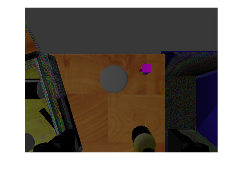

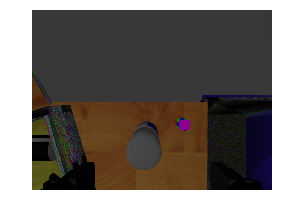

%Ciclo for de la solución 1
clear all
% Configuración inicial del robot
rosIP = '172.17.0.1';
[jointSub,trajGoal,trajAct,gripGoal,gripAct,rgbImgSub,rgbDptSub] = IniciarRobot(rosIP);
q = zeros(6,1);
tiempo_pausa = 2;

% Leemos posiciones de objetos
objeto(1) = struct('objeto', NaN , 'x', 0.325 , 'y',  0.000 , 'z' , -0.08 , 'orientacion',  0.00 , 'Bote', NaN , 'gripper' , NaN);
objeto(2) = struct('objeto', NaN , 'x', 0.343 , 'y', -0.227 , 'z' , -0.08 , 'orientacion', -1.57 , 'Bote', NaN , 'gripper' , NaN);
objeto(3) = struct('objeto', NaN , 'x', 0.325 , 'y',  0.151 , 'z' ,  0.06 , 'orientacion',  0.00 , 'Bote', NaN , 'gripper' , NaN);

bote(1) = struct('color', 0 , 'x', -0.38, 'y', 0.4 , 'z' ,  0.2 , 'orientacion', 0  );
bote(2) = struct('color', 1 , 'x', -0.38, 'y', -0.4 , 'z' ,  0.2 , 'orientacion', 3.14  );

%Ciclo for recorriendo todos los objetos
for n = 1:numel(objeto)
    %Movemos el gripper a posición segura
    gripperX = objeto(n).x;
    gripperY = objeto(n).y;
    gripperZ = objeto(n).z;
    gripperTheta = objeto(n).orientacion;

    q = MoverRobotXYZ(gripperX,gripperY,0.3,gripperTheta,q,trajAct,trajGoal,jointSub);
    pause(tiempo_pausa);
    
    %Ingrese aquí su código para captura de imagen, red neuronal YOLO, y
    %actualización de valores de objeto


    %objeto.objeto(n) = NaN-->{0,1,2,3,4} (Lata,Botella,Spam,Cubo,Plumón) Tipo de objeto
    %objeto.bote(n) = NaN-->{0,1} (Verde,Azul) Lugar de depósito
    %objeto.gripper(n) = NaN -->{(0,1)} Porcentaje de apertura del gripper para cerrarse correctamente 



    %Movemos el gripper a posición de captura 
    q = MoverRobotXYZ(gripperX,gripperY,gripperZ,gripperTheta,q,trajAct,trajGoal,jointSub);
    pause(tiempo_pausa);
    
    %Cerramos gripper
    ValorGripper = objeto(n).gripper;    %0 abierto/desactivado 0.8 cerrado/activado
    ActivacionGripper(ValorGripper,gripAct,gripGoal,jointSub);
    pause(tiempo_pausa);

    %Movemos el gripper a posición segura
    q = MoverRobotXYZ(gripperX,gripperY,0.3,gripperTheta,q,trajAct,trajGoal,jointSub);
    pause(tiempo_pausa);

    %Movemos el gripper a posición bote
    if objeto(n).Bote == bote(1).color
        gripperX = bote(1).x;
        gripperY = bote(1).y;
        gripperZ = bote(1).z;
        gripperTheta = objeto(1).orientacion;
    else
        gripperX = bote(2).x;
        gripperY = bote(2).y;
        gripperZ = bote(2).z;
        gripperTheta = objeto(2).orientacion;
    end
    q = MoverRobotXYZ(gripperX,gripperY,gripperZ,gripperTheta,q,trajAct,trajGoal,jointSub);
    pause(tiempo_pausa);

    %Cerramos gripper
    ValorGripper = 0;    %0 abierto/desactivado 0.8 cerrado/activado
    ActivacionGripper(ValorGripper,gripAct,gripGoal,jointSub);
    pause(tiempo_pausa);

    ValorGripper = 1;    %0 abierto/desactivado 0.8 cerrado/activado
    ActivacionGripper(ValorGripper,gripAct,gripGoal,jointSub);
    pause(tiempo_pausa);

    ValorGripper = 0;    %0 abierto/desactivado 0.8 cerrado/activado
    ActivacionGripper(ValorGripper,gripAct,gripGoal,jointSub);
    pause(tiempo_pausa);

end